**Progetto finale Matlab/Simulink**

- Descrizione modello

Un carroponte è una macchina utilizzata per sollevare e spostare pesanti carichi all'interno di un'area di lavoro, come un magazzino, un cantiere o una fabbrica. Consiste essenzialmente in una struttura metallica a forma di ponte, sorretta da due o più travi poste sopra l'area di lavoro. L’elemento fondamentale è il carrello che si può muovere lungo due direzioni perpendicolari (solitamente su di un sistema di binari) sul piano orizzontale definito dalla struttura. La movimentazione del carrello avviene grazie a motori elettrici. Il carico viene agganciato al carrello tramite un cavo. La distanza tra il carico e il carrello (altezza del carico) può essere regolata per mezzo di un sistema di sollevamento che varia la lunghezza del cavo.

Partendo da un modello fisico, dopo aver definito le rispettive variabili e semplificato l'approcio con le giuste ipotesi, è possibile modellizzare il comportamento del carroponte sotto varie condizioni di carico e di funzionamento. Questo può essere utile per valutare la resistenza strutturale, l'affidabilità e le prestazioni del carroponte prima della sua realizzazione insieme ad un controllo più dettagliato sulle specifiche del modello e la simulazione del comportamento del carroponte.

- Modellazione sistema linearizzato

Dopo aver implementato in Simulink un modello del sistema basato sulle equazioni descritte dal modello fisico, la linearizzazione del sistema può essere effettuata analiticamente oppure in maniera diretta utilizzando il blocco *time based linearization.*

I risultati della linearizzazione vengono salvati nel workspace con una variabile struct. Da qui possiamo estrarre le matrici che caratterizzano il sistema linearizzato.

A = overhead_crane_linearization_model_Timed_Based_Linearization.a;
B = overhead_crane_linearization_model_Linearization.b;
C = overhead_crane_linearization_model_Timed_Based_Linearization.c;
D = overhead_crane_linearization_model_Timed_Based_Linearization.d;

Ottenute le matrici possiamo andare a studiare a la funzione di trasferimento.  

sys = ss(A, B, C, D);
G = tf(sys); 

Nel caso che trattiamo, le funzioni di trasferimento saranno due.

La prima funzione di trasferimento (*Ga*) rappresenta l'angolo (in termini di modulo e fase), mentre la seconda (*Gx*) la posizione.

% Transfer function input to angle
Ga = G(1);

% Transfer function input to position
Gx = G(2);

Nei diagrammi di bode possiamo evidenziare frequenza di taglio e picco di risonanza con il seguente codice e le rispettive figure.

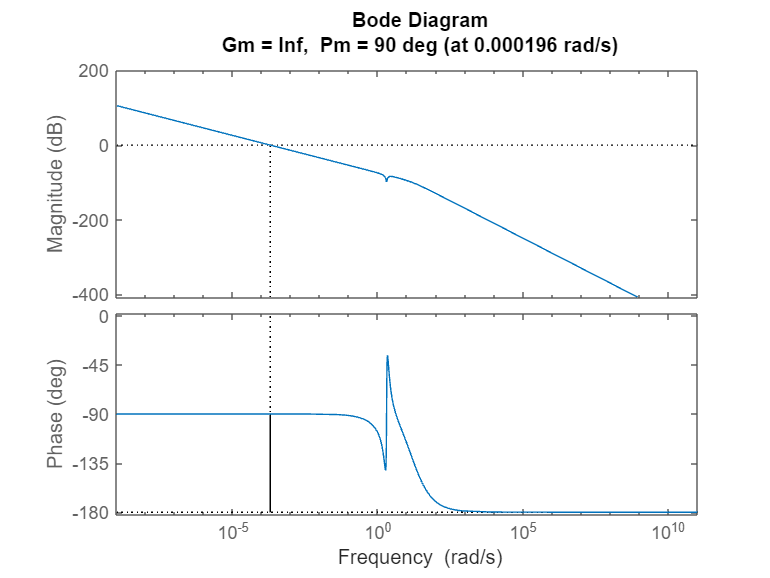

[gm, pm, w_cg, w_cp] = margin(Gx);

% w_cp = 1.9608e-04 frequenza di taglio di Gx

figure;
margin(Gx);
xlim([10e-10, 10e10]);

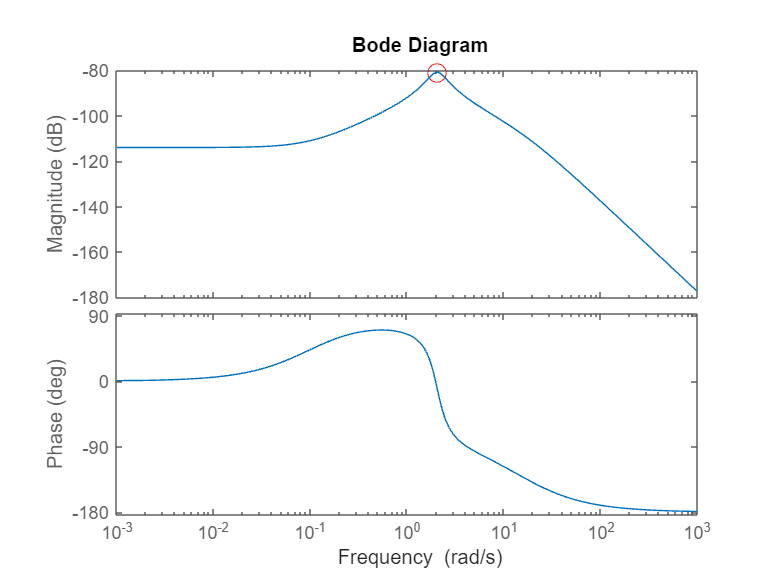

% Segue Bode Diagram di Gx
% Trova il picco di ampiezza in dB
[mag, phase, wout] = bode(Ga);
mag_dB = 20*log10(mag); % Converte il modulo in dB
[mag_peak_dB, idx_peak] = max(mag_dB); % Trova l'indice del picco
freq_peak = wout(idx_peak); % Trova la frequenza corrispondente al picco

% freq_peak = 2.0484 rad/s
% mag_peak_dB = -80.7682 dB

figure;
plot(freq_peak, mag_peak_dB, 'ro', 'MarkerSize', 10);
hold on
bode(Ga);

% Segue Bode Diagram di Ga

Per poter trarre considerazioni e previsioni su stabilità ed eventuali risposte ad input vari, osserviamo la mappatura delle singolarità nei due casi.

Nel caso di *Ga *abbiamo le seguenti singolarità: 

`Poli :  -15.8544 + 0.0000i,  -0.4561 + 1.9999i, -0.4561 - 1.9999i [rad/s]`

`Zeri :  -0.1000 [rad/s]`

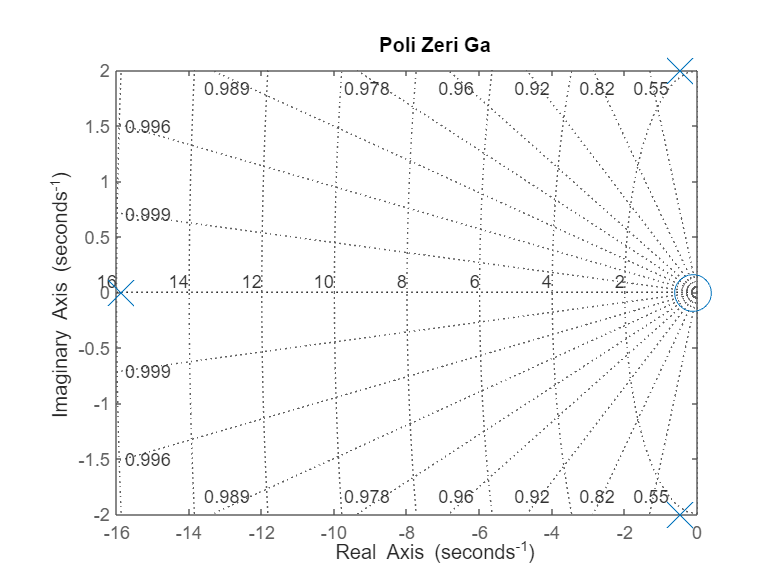

figure;
pzmap(Ga);
title('Poli Zeri Ga');
set(findall(gca, 'type', 'line'), 'markersize', 20);
grid on

Nel caso di *Gx:*

`Poli  :  0.0000 + 0.0000i,  -15.8544 + 0.0000i,  -0.4561 + 1.9999i,  -0.4561 - 1.9999i  [rad/s]`

`Zeri  :  -0.0500 + 1.9803i,  -0.0500 - 1.9803i  [rad/s]`

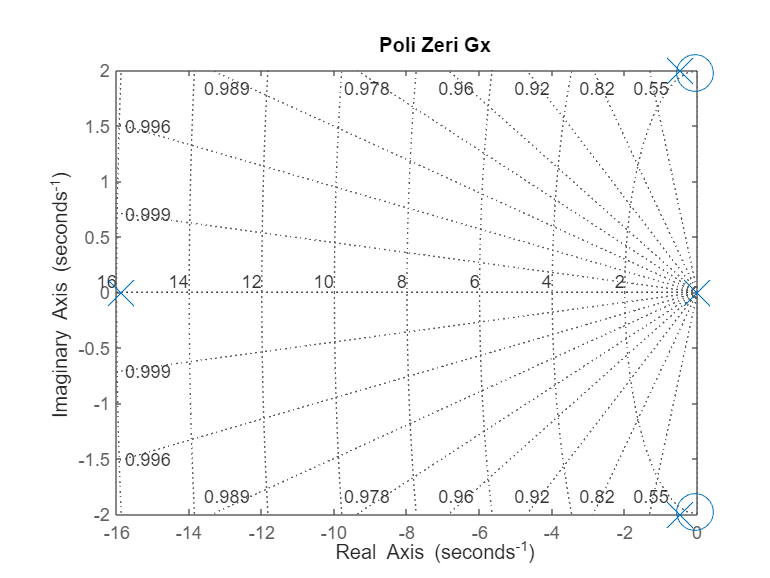

figure;
pzmap(Gx);
title('Poli Zeri Gx');
set(findall(gca, 'type', 'line'), 'markersize', 20);
grid on

Si osservino i grafici delle risposte nel caso linearizzato e non linearizzato messi a confronto. Variabili importate direttamente da modello Simulink.

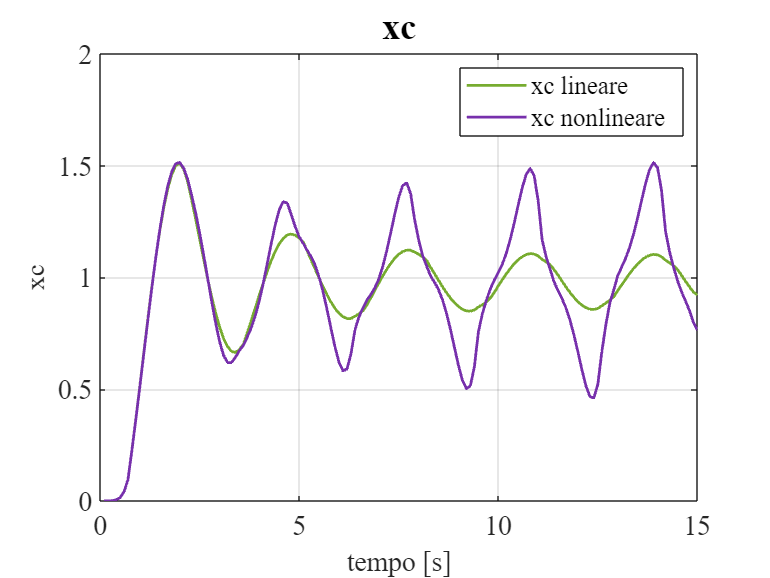

t1 = 0.1:0.1:15;
figure;
plot(t1, out.xc_lineare_simulink, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.4660 0.6740 0.1880])
grid on
ylim([0,2]);
set(gca, 'fontsize', 15, 'fontname', 'times')
title('xc','FontSize',20)
xlabel('tempo [s]', 'fontsize', 15)
ylabel('xc', 'FontSize',15)
hold on
plot(t1, out.xc_non_lineare_simulink, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.4660 0.1880 0.6740])
legend({'xc lineare','xc nonlineare'})

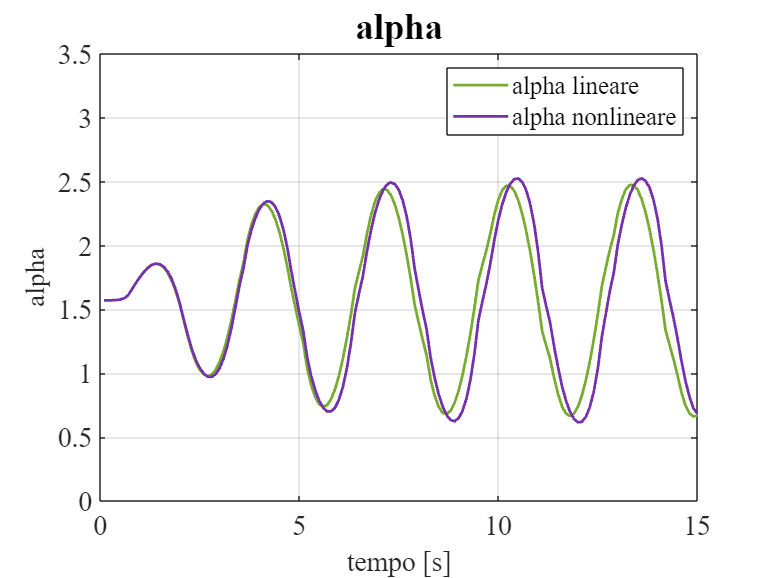


figure;
plot(t1, out.alpha_lineare_simulink, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.4660 0.6740 0.1880])
grid on
ylim([0,3.5]);
set(gca, 'fontsize', 15, 'fontname', 'times')
title('alpha','FontSize',20)
xlabel('tempo [s]', 'fontsize', 15)
ylabel('alpha', 'FontSize',15)
hold on
plot(t1, out.alpha_non_lineare_simulink, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.4660 0.1880 0.6740])
legend({'alpha lineare','alpha nonlineare'})

In conclusione possiamo affermare che il sistema linearizzato offre performance molto distanti dal sistema vero soprattutto in termini di spostamento *xc* (l’effetto delle non linearità è infatti molto più evidente rispetto ad *alpha*).

- Primo progetto del controllore della posizione lineare (xc)

Per quanto riguarda il progetto del controllore, inizialmente abbiamo optato per un semplice controllo proporzionale evitando di andare a cercare soluzioni più avanzate in quanto questo fosse già in grado di garantire errore nullo a regime.

A questo punto, sfruttando il modello del carroponte implementato su simulink, abbiamo aggiunto la linea di retroazione sulla posizione lineare xc e abbiamo inserito nella funzione d'anello il blocco PID Controller solo con il contributo proporzionale. Facendo ciò, a partire dal sistema retroazioneato completo abbiamo potuto visualizzare la risposta di xc attraverso uno scope e conseguentemente procedere con il tuning del controllore proporzionale attraverso il tool PID tuner.

pidTuner;

Aprendo il PID tuner direttamente dal blocco PID controller su simulink, viene importato automaticamente il plant completo (matrice di trasferimento che comprende sia la fdt della posizione lineare che la fdt della posizione quella angolare) . Questo ci ha permesso di regolare tempo di salita, tempo di assestamento e sovraelongazione massima della risposta sulla base delle nostre necessità agendo sul guadagno del controllore prorporzionale. 

Scegliendo Kp=2600 abbiamo ottenuto una risposta con sovraelongazione massima quasi nulla che ci fornisse un tempo di assestamento accettabile. Essendo questa decisione un trade-off tra oscillazioni e tempo di salita, abbiamo pensato di prediligere oscillazioni nulle piuttosto che un sistema particolarmente veloce nella risposta. Una sovraelongazione importante,infatti, potrebbe portare a gravi conseguenze considerando l'ambiente di lavoro di un carroponte, questo infatti è spesso circondato da macchine onerose all'interno delle officine che potrebbero essere colpite dall'argano.

Di seguito si trovano i grafici di posizione angolare, lineare, e azione di controllo relative al controllore proporzionale di cui sopra.

## Plot posizione lineare (xc) proporzionale

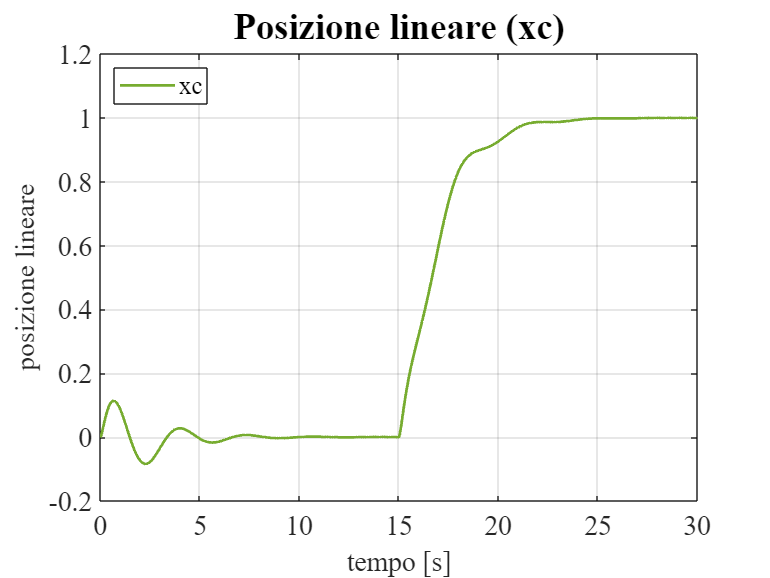

t = 0:0.001:30;
figure;
plot(t, xc_simulink_Proporzionale, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.4660 0.6740 0.1880])
grid on
ylim([-0.2 1.2])
set(gca, 'fontsize', 15, 'fontname', 'times')
title('Posizione lineare (xc)','FontSize',20)
xlabel('tempo [s]', 'fontsize', 15)
ylabel('posizione lineare', 'FontSize',15)
legend({'xc'}, 'Location','northwest')

## Plot posizione angolare (alpha) proporzionale

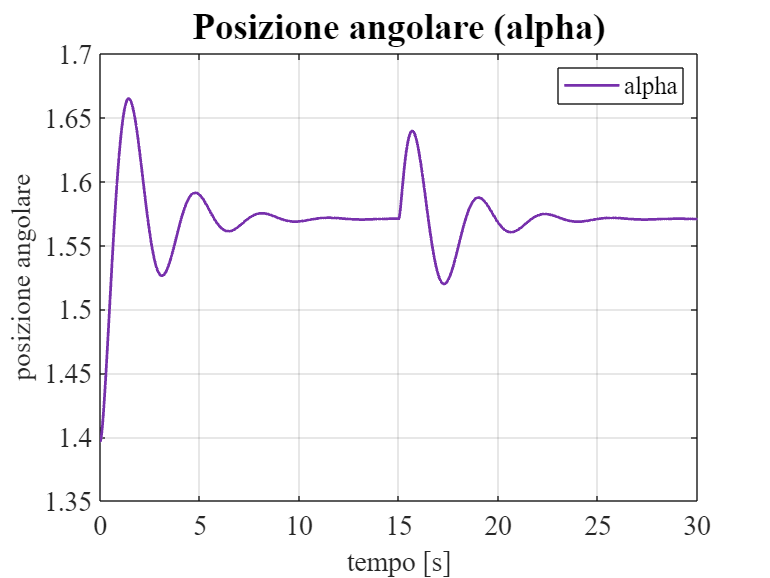

figure;
plot(t, alpha_simulink_Proporzionale, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.4660 0.1880 0.6740])
grid on
set(gca, 'fontsize', 15, 'fontname', 'times')
title('Posizione angolare (alpha)','FontSize',20)
xlabel('tempo [s]', 'fontsize', 15)
ylabel('posizione angolare', 'FontSize',15)
legend({'alpha'})

## Plot azione di controllo (u) proporzionale

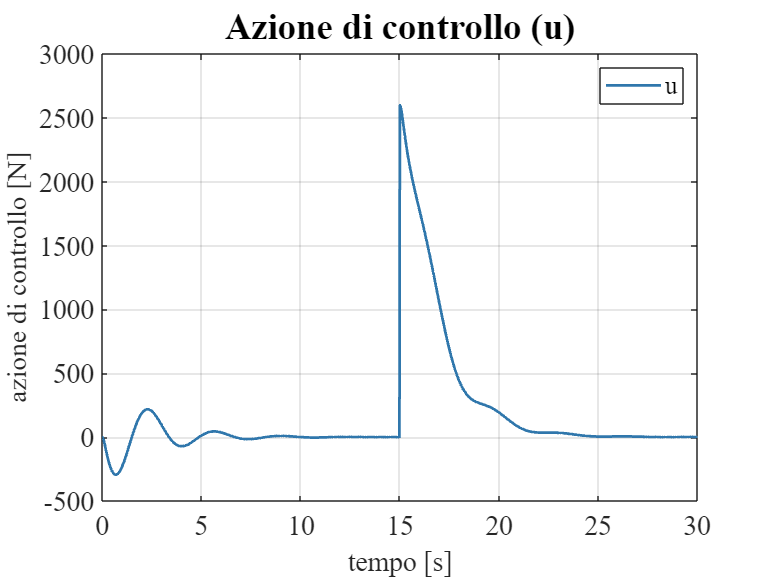

figure;
plot(t, Azione_controllo_simulink_Proporzionale, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.1880 0.4660 0.6740])
grid on
set(gca, 'fontsize', 15, 'fontname', 'times')
title('Azione di controllo (u)','FontSize',20)
xlabel('tempo [s]', 'fontsize', 15)
ylabel('azione di controllo [N]', 'FontSize',15)
legend({'u'})

- Secondo progetto del controllore della posizione lineare (xc)

Per cercare di migliorare il comportamento del sistema abbiamo deciso di progettare un controllore più complesso che ci permettesse di migliorare quanto ottenuto in termini di tempo di salita per il controllore proporzionale, non rinunciando però ad ottenere una risposta con una piccola sovraelongazione massima e osillazioni limitate. Per fare ciò abbiamo deciso di utilizzare il metodo del luogo delle radici per il tuning del controllore, mediante lo studio di Gxc con sisotool.

sisotool(Gxc);

Studiando il luogo delle radici e la risposta a scalino del sistema abbiamo notato che il modo migliore per raggiungere il nostro obiettivo fosse quello di cancellare i poli dominanti complessi coniugati di Gxc in modo da non avere oscillazioni e allo stesso tempo cancellare i due zeri complessi coniugati vicini all'asse immaginario che creano problemi per le sovraelongazioni. A questo punto mancava solo la scelta del guadagno del controllore, abbiamo deciso dunque di optare per quello suggerito nelle soluzioni.

Il controllore trovato dopo questi passaggi è:

s=tf('s');
C = 8000 * (s^2 + 0.9122 * s + 4.208) / (s^2 + 0.1 * s + 3.924)

C =
 
  8000 s^2 + 7298 s + 33664
  -------------------------
     s^2 + 0.1 s + 3.924
 
Continuous-time transfer function.
Model Properties


## Plot posizione lineare (xc) controllore dinamico

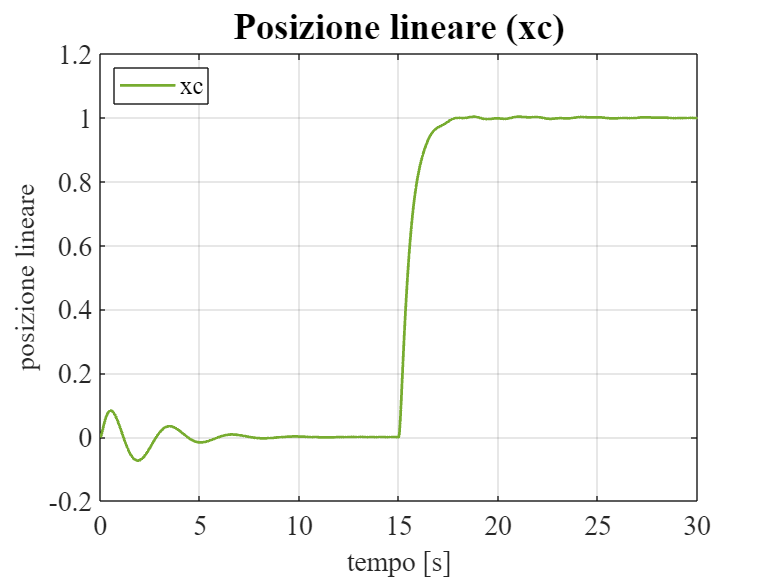

figure;
plot(t, xc_simulink_Dinamico, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.4660 0.6740 0.1880])
grid on
set(gca, 'fontsize', 15, 'fontname', 'times')
title('Posizione lineare (xc)','FontSize',20)
xlabel('tempo [s]', 'fontsize', 15)
ylabel('posizione lineare', 'FontSize',15)
legend({'xc'}, 'Location', 'northwest')

## Plot posizione angolare (alpha) controllore dinamico

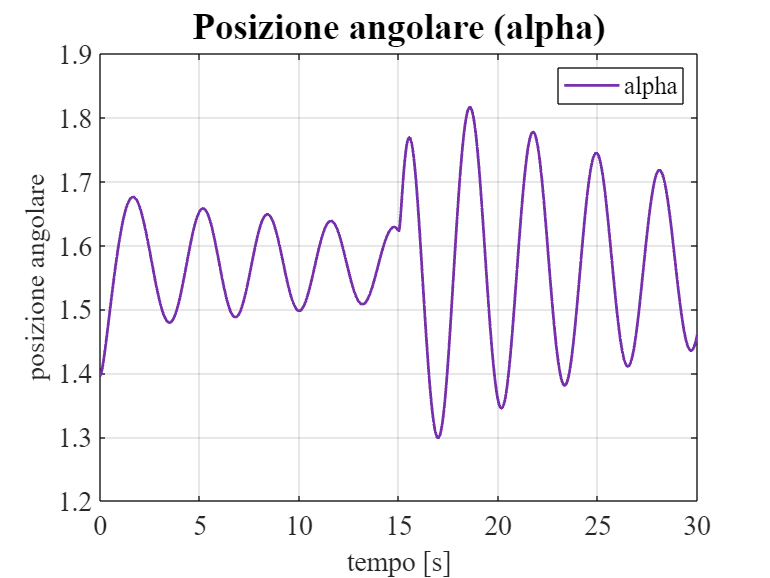

figure;
plot(t, alpha_simulink_Dinamico, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.4660 0.1880 0.6740])
grid on
set(gca, 'fontsize', 15, 'fontname', 'times')
title('Posizione angolare (alpha)','FontSize',20)
xlabel('tempo [s]', 'fontsize', 15)
ylabel('posizione angolare', 'FontSize',15)
legend({'alpha'})

## Plot azione di controllo (u) controllore dinamico

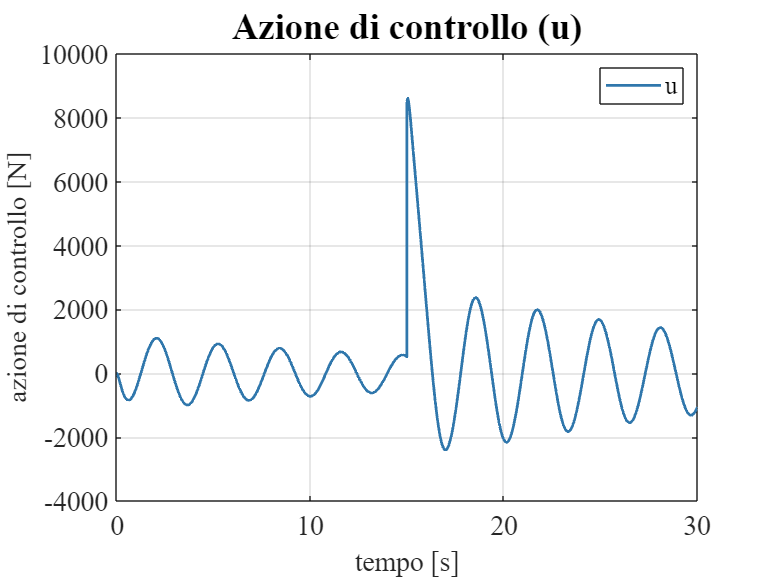

figure;
plot(t, Azione_controllo_simulink_Dinamico, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.1880 0.4660 0.6740])
grid on
set(gca, 'fontsize', 15, 'fontname', 'times')
title('Azione di controllo (u)','FontSize',20)
xlabel('tempo [s]', 'fontsize', 15)
ylabel('azione di controllo [N]', 'FontSize',15)
legend({'u'})

Come si può vedere dalle varie risposte questo controllore si comporta molto bene per quanto riguarda il controllo della posizione lineare xc, ma ha effetti negativi sia per quanto riguarda la posizione angolare (alpha) che per quanto riguarda l'azione di controllo (u).

Con C1 si fa riferimento al primo progetto, ovvero quello proporzionale, mentre con C2 al secondo, ovvero quello dinamico.

## Comparazione posizione lineare

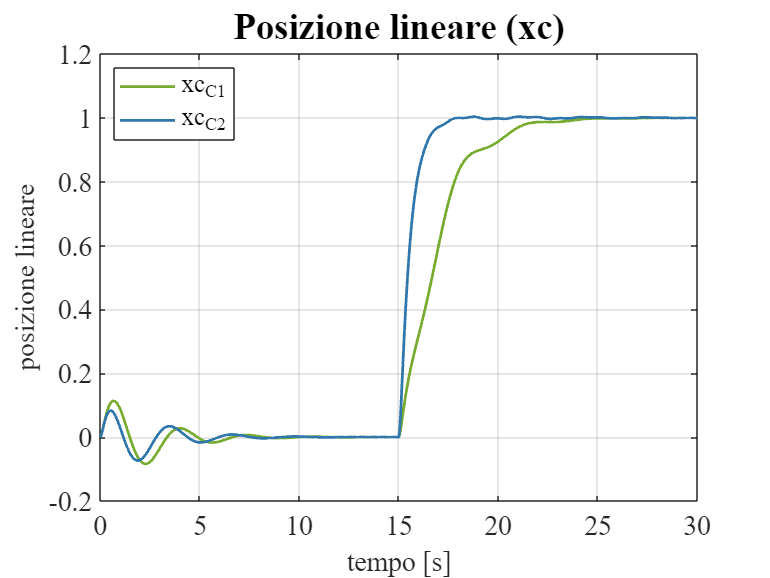

figure;
plot(t, xc_simulink_Proporzionale, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.4660 0.6740 0.1880])
hold on
plot(t, xc_simulink_Dinamico, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.1880 0.4660 0.6740])
grid on
set(gca, 'fontsize', 15, 'fontname', 'times')
title('Posizione lineare (xc)','FontSize',20)
xlabel('tempo [s]', 'fontsize', 15)
ylabel('posizione lineare', 'FontSize',15)
legend({'xc_C1', 'xc_C2'}, 'Location', 'northwest')

## Comparazione posizione angolare

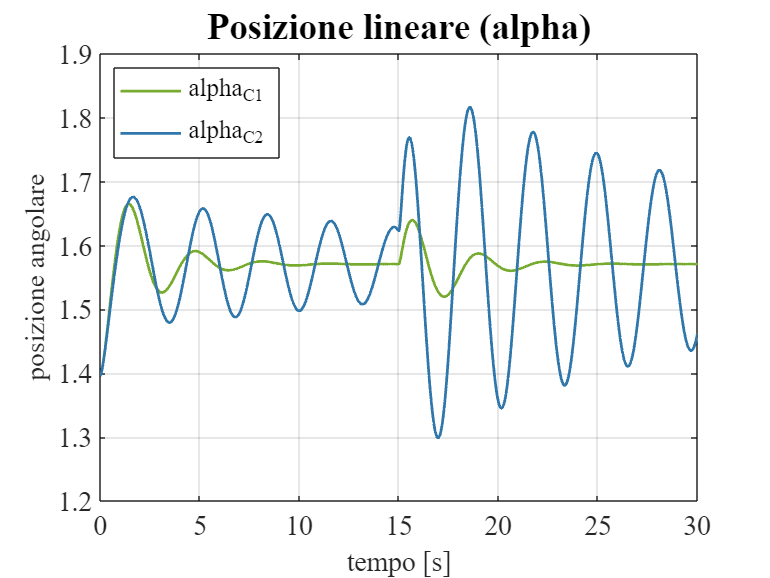

figure;
plot(t, alpha_simulink_Proporzionale, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.4660 0.6740 0.1880])
hold on
plot(t, alpha_simulink_Dinamico, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.1880 0.4660 0.6740])
grid on
set(gca, 'fontsize', 15, 'fontname', 'times')
title('Posizione lineare (alpha)','FontSize',20)
xlabel('tempo [s]', 'fontsize', 15)
ylabel('posizione angolare', 'FontSize',15)
legend({'alpha_C1', 'alpha_C2'}, 'Location', 'northwest')

## Comparazione azione di controllo

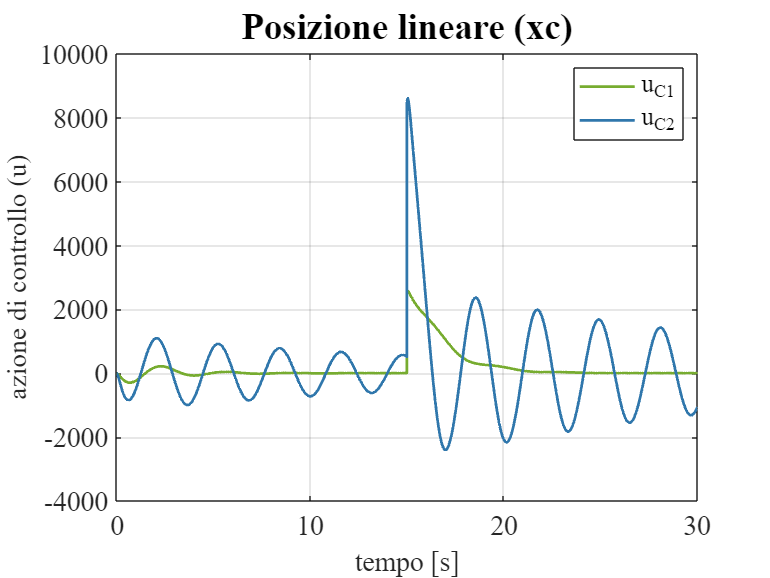

figure;
plot(t, Azione_controllo_simulink_Proporzionale, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.4660 0.6740 0.1880])
hold on
plot(t, Azione_controllo_simulink_Dinamico, 'LineWidth',1.5, 'LineStyle','-', 'Color', [0.1880 0.4660 0.6740])
grid on
set(gca, 'fontsize', 15, 'fontname', 'times')
title('Posizione lineare (xc)','FontSize',20)
xlabel('tempo [s]', 'fontsize', 15)
ylabel('azione di controllo (u)', 'FontSize',15)
legend({'u_C1', 'u_C2'})